clear all
% data=readtable("C:\Users\thoma\Downloads\book1.xlsx")
data=readtable("C:\Users\thoma\Documents\optionogaktieprisereurostoxx50pronmdex.xlsx",'Sheet','Sheet1','Range','A2:H1602')

data = 1600×8 table
       Date       LastPrice      Volume      SMAVG_15_       Date_1      LastPrice_1     Volume_1     SMAVG_15__1
    __________    _________    __________    __________    __________    ___________    __________    ___________

    27/03/2019     3321.4               0    4.3575e+08    27/03/2019      3321.4       8.3889e+08    2.1031e+09 
    26/03/2019     3319.5      4.3421e+08    4.6148e+08    22/03/2019      3305.7         2.15e+09    2.2099e+09 
    25/03/2019     3300.5      4.0468e+08    4.5612e+08    15/03/2019      3386.1         2.48e+09    2.2339e+09 
    22/03/2019     3305.7      6.6747e+08    4.4874e+08    08/03/2019      3283.6          2.1e+09    2.2152e+09 
    21/03/2019     3367


%Vender data om.
data=flipud(data)

data = 1600×8 table
       Date       LastPrice      Volume      SMAVG_15_     Date_1    LastPrice_1    Volume_1    SMAVG_15__1
    __________    _________    __________    __________    ______    ___________    ________    ___________

    31/12/2012     2635.9      1.0315e+08     7.003e+08     NaT          NaN          NaN           NaN    
    02/01/2013     2711.3      1.0315e+09    7.2357e+08     NaT          NaN          NaN           NaN    
    03/01/2013     2701.2      8.9775e+08    7.2366e+08     NaT          NaN          NaN           NaN    
    04/01/2013     2709.3      8.2507e+08    7.3206e+08     NaT          NaN          NaN           NaN    
    07/01/2013     2695.6      8.0569e+08    7.3419e+08    

dates=datetime(data.Date,'Convertfrom','excel');
logreturn=[nan;diff(log(data.LastPrice))]*100

logreturn =        NaN
    2.8174
   -0.3706
    0.3005
   -0.5103
   -0.1526
    0.5536
    0.0694
    0.3509
   -0.0968


% Startværdier og begrænsninger for koefficienterne. 
%Første er konstant i varians. Næste er alpha og den sidste er
%risikopræmien
initialvaerdier = [1,0.05,0.9,0.1,0.1]

initialvaerdier =     1.0000    0.0500    0.9000    0.1000    0.1000


Ovenfor=[inf 1 1 inf 1]

Ovenfor =    Inf     1     1   Inf     1


Nedenfor=[0 0 0 0 -1]

Nedenfor =      0     0     0     0    -1


T=size(logreturn,1)

T = 1600

A=[0 1 1 0 0];
b=1;
%backcast funktion til at sætte gang i algoritmen.
w = .05*.9.^(0:T-2);
backCast= w.*logreturn(2:end).^2;
backCast=0.01

backCast = 0.0100

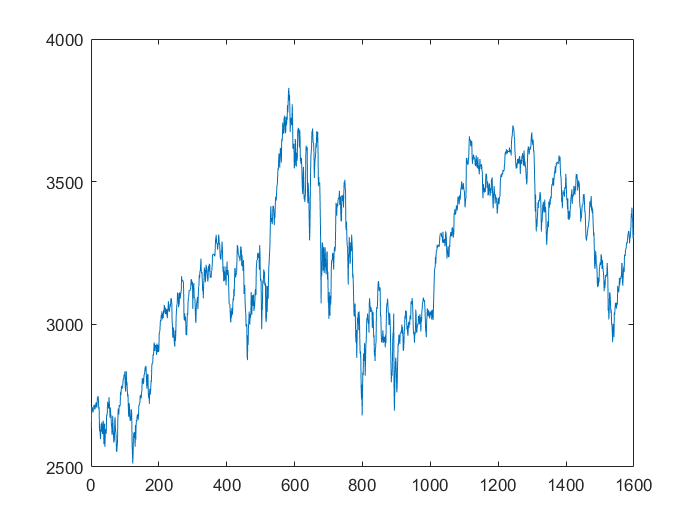

%Indstillinger for fmincon.
options = optimset('fmincon');
options.Display = 'iter';
options.Algorithm = 'sqp';
options.Functiontolerance=1/100000000000;
options.TolCon=1/100000000000;
plot(data.LastPrice)

%Det er her jeg kalder funktionen defineret i bunden:
%fejlled=logreturn-r/251+h/2-lambda*sqrt(h). Fejlled=epsilon,
%logreturn=y=det simulerede afkast, h=den betingede varians

% variansen er defineret som h(i)=c+beta*h(i-1)+alpha*(fejlled(i-1)).^2;
% Samme definition som ovenover
 [estimates2,fval,exitflag,output,lambda,gradient,hessian] = fmincon(@ARMA_GARCH,initialvaerdier,A,b,[],[],Nedenfor,Ovenfor,[],options,logreturn(2:end),backCast);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    2.444655e+03     0.000e+00     1.000e+00     0.000e+00     2.503e+02  
Objective function returned NaN; trying a new point...
    1          15    2.428711e+03     0.000e+00     3.430e-01     5.973e-01     4.610e+02  
Objective function returned NaN; trying a new point...
    2          26    2.411496e+03     0.000e+00     1.681e-01     2.545e-01     6.312e+02  
    3          44    2.409039e+03     0.000e+00     1.384e-02     1.106e-01     5.459e+02  
    4          53    2.367325e+03     0.000e+00     3.430e-01     4.007e-01     1.625e+02  
    5          60    2.330602e+03     0.000e+00     7.000e-01     6.357e-01     9.039e+02  
    6          73    2.326198e+03     0.000e+00     8.235e-02     1.010e-01     4.278e+02  
    7          92    2.324789e+03     0.000e+00     9.689e-03   


fval

fval = 2.2692e+03

exitflag

exitflag = 2

output

output = struct with fields:
         iterations: 24
          funcCount: 209
          algorithm: 'sqp'
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the default value of the step size tolerance and constraints are ↵satisfied to within the selected value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-11.↵↵Optimization Metric                                           Options↵max(abs(delta_x./x)) =   9.63e-08                       StepTolerance =   1e-06 (default)↵relative max(constraint violation) =   0.00e+00   ConstraintTolerance =   1e-11 (selected)'
    constrviolation: 0
           stepsize: 1.8942e-07
       lssteplength: 0.7000
      firstorderopt

lambda

lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: [0×1 double]
       ineqlin: 0
    ineqnonlin: [0×1 double]
         lower: [5×1 double]
         upper: [5×1 double]


%Tjek førsteordensbetingelser.
gradient

gradient =    -0.0016
   -0.0010
   -0.0012
   -0.0002
    0.0002


hessian

hessian = 	1.0e+04 *

    9.0562    6.8547    4.9095    0.0105   -0.0214
    6.8547    6.5312    5.0460    0.0263   -0.0032
    4.9095    5.0460    4.3917   -0.0160   -0.0052
    0.0105    0.0263   -0.0160    0.1917    0.0143
   -0.0214   -0.0032   -0.0052    0.0143    0.1474


eig(hessian)

ans = 	1.0e+05 *

    0.0143
    0.0161
    0.0218
    0.1499
    1.8297


%Tjek for maksimum
any(eig(hessian)<=0)

ans = logical
   0


%Jeg henter fejlled og h ud for at kunne finde standardfejlene.
[ll,lls,h,fejlled]=ARMA_GARCH(estimates2,logreturn(2:end),backCast);
h

h =     0.0100
    0.0407
    0.0743
    0.1029
    0.1495
    0.1683
    0.2044
    0.2125
    0.2286
    0.2348


%Standardiseret fejl og test
bic=aicbic(ll,length(estimates2),length(logreturn(2:end)))

bic = -4.5284e+03

ll

ll = 2.2692e+03

standardfejl=fejlled./sqrt(h)

standardfejl =          0
   -1.2999
    0.8855
   -1.6654
   -0.5667
    1.2331
    0.1301
    0.6831
   -0.2470
   -1.1265


[h,pValue,stat,cValue]=lbqtest(standardfejl,'lags',5)

h = logical
   0


pValue = 0.1138

stat = 8.8845

cValue = 11.0705

[h,pValue,stat,cValue]=lbqtest(standardfejl.^2,'lags',4)

h = logical
   0


pValue = 0.9247

stat = 0.8990

cValue = 9.4877

%første moment
mean(standardfejl)

ans = -0.0368

%andet moment
mean(standardfejl.^2)

ans = 0.9995

%tredje moment
mean(standardfejl.^3)

ans = -0.4493

%fjerde moment
mean(standardfejl.^4)

ans = 5.2722

%Test statistik. Normalitet
[h,p,jbstat,critval]=jbtest(standardfejl)

h = 1

p = 1.0000e-03

jbstat = 363.1543

critval = 5.9546



% plot(dates(2:end),zminus,'blue',dates(2:end),zplus,'blue',dates(2:end),z,'red')
 

%%%Her regner jeg standardfejlene ud ved sandwhichformlen.
%approximation af differentialet for at beregne varians nedenunder finder jeg I i sandwhichformlen
%Først tager jeg en meget lille ændring til hvert af parametrene.
forskel=0.00001*estimates2

forskel = 	1.0e+-5 *

    0.0319    0.8818    0.0942    0.0397   -0.0525


antal=length(estimates2)

antal = 5

bidrag=zeros(T-1,antal);
for i=1:antal
    j=forskel(i)
    delta=zeros(1,antal);
    delta(i)=j;
%     Jeg finder ændringen i loglikelihood, hvis jeg bruger en smule større og mindre estimater.
    [~, loglikelidtover]= ARMA_GARCH(estimates2+delta,logreturn(2:end),backCast);
    [~, loglikelidtunder]=ARMA_GARCH(estimates2-delta,logreturn(2:end),backCast);
    bidrag(:,i)=(loglikelidtover-loglikelidtunder)/(2*j)
        J_i=bidrag(i)*bidrag(i)'
end

j = 3.1896e-07

bidrag =          0         0         0         0         0
   -8.4695         0         0         0         0
    2.7345         0         0         0         0
  -22.9212         0         0         0         0
    7.5949         0         0         0         0
   -6.1106         0         0         0         0
   10.7818         0         0         0         0
    6.2185         0         0         0         0
   11.0257         0         0         0         0
   -3.2842         0         0         0         0


J_i = 0

j = 8.8183e-06

bidrag =          0         0         0         0         0
   -8.4695   -0.0847         0         0         0
    2.7345    0.0720         0         0         0
  -22.9212   -1.0167         0         0         0
    7.5949    0.4698         0         0         0
   -6.1106   -0.5136         0         0         0
   10.7818    1.1087         0         0         0
    6.2185    0.7669         0         0         0
   11.0257    1.5429         0         0         0
   -3.2842   -0.5104         0         0         0


J_i = 71.7321

j = 9.4217e-07

bidrag =          0         0         0         0         0
   -8.4695   -0.0847         0         0         0
    2.7345    0.0720    0.1000         0         0
  -22.9212   -1.0167   -1.0249         0         0
    7.5949    0.4698    0.8859         0         0
   -6.1106   -0.5136   -0.6066         0         0
   10.7818    1.1087    1.4469         0         0
    6.2185    0.7669    0.6704         0         0
   11.0257    1.5429    1.1708         0         0
   -3.2842   -0.5104   -0.2959         0         0


J_i = 7.4775

j = 3.9706e-07

bidrag =          0         0         0         0         0
   -8.4695   -0.0847         0    6.4421         0
    2.7345    0.0720    0.1000   -3.1772         0
  -22.9212   -1.0167   -1.0249    5.2083         0
    7.5949    0.4698    0.8859    1.6902         0
   -6.1106   -0.5136   -0.6066   -3.2051         0
   10.7818    1.1087    1.4469   -0.2443         0
    6.2185    0.7669    0.6704   -1.4758         0
   11.0257    1.5429    1.1708    0.4035         0
   -3.2842   -0.5104   -0.2959    2.3399         0


J_i = 525.3791

j = -5.2548e-07

bidrag =          0         0         0         0         0
   -8.4695   -0.0847         0    6.4421   18.1497
    2.7345    0.0720    0.1000   -3.1772    1.4065
  -22.9212   -1.0167   -1.0249    5.2083    0.3567
    7.5949    0.4698    0.8859    1.6902   -0.3995
   -6.1106   -0.5136   -0.6066   -3.2051    0.2820
   10.7818    1.1087    1.4469   -0.2443    0.1179
    6.2185    0.7669    0.6704   -1.4758    0.0170
   11.0257    1.5429    1.1708    0.4035    0.3458
   -3.2842   -0.5104   -0.2959    2.3399   -0.2700


J_i = 57.6820


I=bidrag'*bidrag/T

I =   138.6459   95.3608   67.1900   -0.7492   -0.7462
   95.3608   84.2696   65.5901   -1.2434   -1.1155
   67.1900   65.5901   58.8393   -1.1243   -1.6272
   -0.7492   -1.2434   -1.1243    1.3356    0.0402
   -0.7462   -1.1155   -1.6272    0.0402    1.2858


%Så skal J findes
J=hessian_beggesider(@ARMA_GARCH, estimates2, logreturn(2:end), backCast)

J = 	1.0e+16 *

   -1.1152   -0.0403   -0.3775   -0.8959   -0.6769
   -0.0403   -0.0015   -0.0137   -0.0324   -0.0245
   -0.3775   -0.0137   -0.1278   -0.3033   -0.2292
   -0.8959   -0.0324   -0.3033   -0.7197   -0.5438
   -0.6769   -0.0245   -0.2292   -0.5438   -0.4109


J=J/T

J = 	1.0e+12 *

   -6.9701   -0.2521   -2.3597   -5.5992   -4.2308
   -0.2521   -0.0091   -0.0853   -0.2025   -0.1530
   -2.3597   -0.0853   -0.7988   -1.8955   -1.4323
   -5.5992   -0.2025   -1.8955   -4.4979   -3.3987
   -4.2308   -0.1530   -1.4323   -3.3987   -2.5681


%Her invetere jeg J.
Jinv=J\eye(length(J))

Jinv =     0.1576   -0.2361    0.0909   -0.1324   -0.1211
   -0.2361    0.7589   -0.5980    0.2582    0.3355
    0.0909   -0.5980    0.6492   -0.1601   -0.2642
   -0.1323    0.2581   -0.1601    0.8476   -0.8298
   -0.1211    0.3356   -0.2643   -0.8297    1.4250



% Så kombineres J og I ved sandwhichformlen
vcv=Jinv*I*Jinv/T

vcv =     0.0004   -0.0005    0.0002   -0.0003   -0.0004
   -0.0005    0.0019   -0.0016    0.0003    0.0013
    0.0002   -0.0016    0.0019   -0.0000   -0.0012
   -0.0003    0.0003   -0.0000    0.0013   -0.0012
   -0.0004    0.0013   -0.0012   -0.0012    0.0028


%Nu tager jeg kvadratroden af diagonalen og får standardafvigelserne for
%parametrene
se=sqrt(diag(vcv))

se =     0.0204
    0.0431
    0.0440
    0.0359
    0.0527


%Så er standardfejlene fundet
estimates2

estimates2 =     0.0319    0.8818    0.0942    0.0397   -0.0525


name={'omega';'alpha';'beta';'phi';'phi1'};





%Her definerer jeg koefficienterne. Jeg dividerer omega som er konstanten i variansen med 100 i anden
omega=estimates2(:,1)/(100.^2) 

omega = 3.1896e-06

omega=estimates2(:,1)

omega = 0.0319

beta=estimates2(:,3)

beta = 0.0942

alpha=estimates2(:,2)

alpha = 0.8818

konstant=estimates2(:,4)

konstant = 0.0397

konstant2=estimates2(:,5)

konstant2 = -0.0525

% lambda=estimates2(:,5)
%Og her smider jeg koefficienterne ind i en tabel for at få overblik
standardafvigelse=[se']

standardafvigelse =     0.0204    0.0431    0.0440    0.0359    0.0527


parametre=[omega alpha beta konstant konstant2]

parametre =     0.0319    0.8818    0.0942    0.0397   -0.0525


tfejl=parametre./standardafvigelse

tfejl =     1.5642   20.4828    2.1400    1.1061   -0.9965


table(name, parametre',standardafvigelse',tfejl')

ans = 5×4 table
     name        Var2         Var3        Var4  
    _______    _________    ________    ________

    'omega'     0.031896    0.020392      1.5642
    'alpha'      0.88183    0.043052      20.483
    'beta'      0.094217    0.044027        2.14
    'phi'       0.039706    0.035897      1.1061
    'phi1'     -0.052548    0.052734    -0.99646


omega=estimates2(:,1)/(100^2)

omega = 3.1896e-06

[ll,lls,h,fejlled]=ARMA_GARCH(estimates2,logreturn(2:end),backCast);

%Simulation af indeksværdi
%Først trækker jeg noge tilfældige tal fra normalfordelingen
rng(2)
tilfaeldige=randn(502,100000);
%Så allokere jeg plads til variablerne
sigma2=zeros(502,100000);
sigma2(1,:)=h(end)./10000

sigma2 = 	1.0e+-4 *

    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029    0.8029
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

y=zeros(502,100000);
S=zeros(502,100000);
%Jeg definerer den samlede portefølje til en i første periode. obs jeg har
%ændret den fra det simon sagde igen
S(1,:)=data.LastPrice(end)

S = 	1.0e+03 *

    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214    3.3214
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

S0=data.LastPrice(end)

S0 = 3.3214e+03

%  S(1,:)=data.PX_LAST(end);
 akkumuleretafkast=zeros(502,100000);
 %Jeg simulerer y(t)=r-1/2*h(t)+epsilon(t). Som afkast under Q
 %Den betingede varians er givet ved
 %h(t)=omega+alpha*epsilon(t-1)^2+beta*h(t-1)
 r=(1+0.001235)^(1/251)-1;

 tic
for j=1:100000
    for i=2:453
        %sigma2 er den betingede varians
        sigma2(i,j)=omega+beta*sigma2(i-1,j)+alpha*(tilfaeldige(i-1,j)*sqrt(sigma2(i-1,j)))^2;
        %y er det daglige afkast givet ved 
        y(i,j)=sqrt(sigma2(i,j))*tilfaeldige(i,j)+(r)-sigma2(i,j)/2;
        %jeg samler de daglige afkast i r og tager tilsidst eksponential
        %funktionen til r i de enkelte periode.
        akkumuleretafkast(i,j)=y(i,j)+akkumuleretafkast(i-1,j);
        S(i,j)=exp(akkumuleretafkast(i,j))*S0;
    end
end
toc

Elapsed time is 228.944377 seconds.


% %strike
% % K=
y

y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0087    0.0035   -0.0024    0.0011    0.0085    0.0023   -0.0144   -0.0055   -0.0029   -0.0014   -0.0012   -0.0007   -0.0268   -0.0123    0.0024   -0.0086   -0.0026   -0.0044   -0.0004    0.0191    0.0055    0.0073    0.0086   -0.0001    0.0010    0.0011   -0.0330   -0.0059   -0.0077    0.0104    0.0014    0.0128   -0.0014   -0.0049   -0.0169    0.0049   -0.0002   -0.0089   -0.0014    0.0000    0.0019   -0.0008    0.0139    0.0014    0.0016    0.0040   -0.0238    0.0026    0.0068    0

akkumuleretafkast

akkumuleretafkast =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0087    0.0035   -0.0024    0.0011    0.0085    0.0023   -0.0144   -0.0055   -0.0029   -0.0014   -0.0012   -0.0007   -0.0268   -0.0123    0.0024   -0.0086   -0.0026   -0.0044   -0.0004    0.0191    0.0055    0.0073    0.0086   -0.0001    0.0010    0.0011   -0.0330   -0.0059   -0.0077    0.0104    0.0014    0.0128   -0.0014   -0.0049   -0.0169    0.0049   -0.0002   -0.0089   -0.0014    0.0000    0.0019   -0.0008    0.0139    0.0014    0.0016    0.0040   -0.0238    0.002

S

S = 	1.0e+05 *

    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332    0.0332
    0.0329    0.0333    0.0331    0.0333    0.0335    0.0333    0.0327    0.0330    0.0331    0.0332    0.0332    0.0332    0.0323    0.0328    0.0333    0.0329    0.0331    0.0331    0.0332    0.0339    0.0334    0.0335    0.0335    0.0332    0.0332    0.0333    0.0321    0.0330    0.0330    0.0336    0.0333    0.0336    0.0332    0.0331    0.0327    0.0334    0.0332    0.0329    0.0332    0.0332    0.0333    0.0332    0.0337    0.0333    0.0333    0.0333    0.0324    0.0333   

faktiskepriser=readtable("C:\Users\thoma\Documents\optionogaktieprisereurostoxx50pronmdex.xlsx",'Sheet','Worksheet')

faktiskepriser = 60×11 table
                               Strike                                    Ticker        Bid     Ask     Last     IVM      Volm    Var8    Var9    Var10      Var11   
    _____________________________________________________________    ______________    ____    ____    ____    ______    ____    ____    ____    _____    __________

    '18-Apr-19 (22d); CSize 10; IDiv 3.96; R -.37; IFwd 3314.53'     ''                 NaN     NaN     NaN       NaN     NaN     NaN    NaN      NaN            NaT
    '3275'                                                           'SX5E 4 C3275'    67.5    69.1  


% fakoption=faktiskepriser.Last.*(volume>100);
% sum((fakoption>0))
fakoption=[49.8,36.7,26,15.5,50.3,21.2,58,41.4,92,189.2,90]

fakoption =    49.8000   36.7000   26.0000   15.5000   50.3000   21.2000   58.0000   41.4000   92.0000  189.2000   90.0000


% 

% %Tilsidst findes optionspriserne ved at tilbagediskontere gennemsnittet af max(S_t-K,0)
%en måned frem. 22 dage
r=(1+0.001235)^(1/251)-1

r = 4.9173e-06

R=(r+1)

R = 1.0000

option1maaned=zeros(1,10)

option1maaned =      0     0     0     0     0     0     0     0     0     0


K=3300

K = 3300

option1maaned(1,1)=mean(max(S(22,:)-K,0))*exp(-((R)^22-1))

option1maaned =    46.4218         0         0         0         0         0         0         0         0         0


K=3325

K = 3325

option1maaned(1,2)=mean(max(S(22,:)-K,0))*exp(-((R)^22-1))

option1maaned =    46.4218   32.5715         0         0         0         0         0         0         0         0


K=3350

K = 3350

option1maaned(1,3)=mean(max(S(22,:)-K,0))*exp(-((R)^22-1))

option1maaned =    46.4218   32.5715   22.6580         0         0         0         0         0         0         0


K=3375

K = 3375

option1maaned(1,4)=mean(max(S(22,:)-K,0))*exp(-((R)^22-1))

option1maaned =    46.4218   32.5715   22.6580   16.1201         0         0         0         0         0         0



%to måneder frem. 51 dage.
K=3300

K = 3300

option1maaned(1,5)=mean(max(S(51,:)-K,0))*exp(-((R)^51-1))

option1maaned =    46.4218   32.5715   22.6580   16.1201   63.6606         0         0         0         0         0


K=3375

K = 3375

option1maaned(1,6)=mean(max(S(51,:)-K,0))*exp(-((R)^51-1))

option1maaned =    46.4218   32.5715   22.6580   16.1201   63.6606   31.0002         0         0         0         0



%tre måneder frem. 86 dage
K=3300

K = 3300

option1maaned(1,7)=mean(max(S(86,:)-K,0))*exp(-((R)^86-1))

option1maaned =    46.4218   32.5715   22.6580   16.1201   63.6606   31.0002   79.8452         0         0         0


K=3350

K = 3350

%seks måneder frem. 177 dage
K=3300

K = 3300

option1maaned(1,8)=mean(max(S(177,:)-K,0))*exp(-((R)^177-1))

option1maaned =    46.4218   32.5715   22.6580   16.1201   63.6606   31.0002   79.8452  113.1492         0         0


%20 marts 2020 359 dage frem
K=3200

K = 3200

option1maaned(1,9)=mean(max(S(359,:)-K,0))*exp(-((R)^359-1))

option1maaned =    46.4218   32.5715   22.6580   16.1201   63.6606   31.0002   79.8452  113.1492  218.8233         0


%19 juni 2020 450 dage frem
K=3400

K = 3400

option1maaned(1,10)=mean(max(S(450,:)-K,0))*exp(-((R)^450-1))

option1maaned =    46.4218   32.5715   22.6580   16.1201   63.6606   31.0002   79.8452  113.1492  218.8233  134.9392



T=[22,22,22,22,51,51,86,177];
K=[3300,3325,3350,3375,3300,3375,3300,3300];
T=T/251

T =     0.0876    0.0876    0.0876    0.0876    0.2032    0.2032    0.3426    0.7052


Volatility = blsimpv(S0,K,r,T,option1maaned(1:8))

Volatility =     0.0886    0.0875    0.0891    0.0933    0.0878    0.0890    0.0887    0.0921


Volatility = blsimpv(S0,K,r,T,option1maaned(1:8))

Volatility =     0.0886    0.0875    0.0891    0.0933    0.0878    0.0890    0.0887    0.0921


for i=1:8
SE(i)=(option1maaned(i)-fakoption(i)).^2
end

SE = 11.4123

SE =    11.4123   17.0447


SE =    11.4123   17.0447   11.1690


SE =    11.4123   17.0447   11.1690    0.3845


SE =    11.4123   17.0447   11.1690    0.3845  178.5068


SE =    11.4123   17.0447   11.1690    0.3845  178.5068   96.0439


SE =    11.4123   17.0447   11.1690    0.3845  178.5068   96.0439  477.2140


SE =     0.0114    0.0170    0.0112    0.0004    0.1785    0.0960    0.4772    5.1480



K=[3300,3325,3350,3375,3300,3375,3300,3300];
3300/S0

ans = 0.9935

3325/S0

ans = 1.0011

3350/S0

ans = 1.0086

3375/S0

ans = 1.0161

SE

SE =     0.0114    0.0170    0.0112    0.0004    0.1785    0.0960    0.4772    5.1480


%Fordelt på K
%Total
j=length(K)

j = 8

RMSEtot=sqrt(sum(SE(1:8))./sum(j))

RMSEtot = 27.2482

%K=3300
j=K==3300

j = 1×8 logical array
   1   0   0   0   1   0   1   1


RMSEtot=sqrt(sum(SE(1:8).*j)./sum(j))

RMSEtot = 38.1284

%K=3325
j=K==3325

j = 1×8 logical array
   0   1   0   0   0   0   0   0


RMSEtot=sqrt(sum(SE(1:8).*j)./sum(j))

RMSEtot = 4.1285

%K=3350
j=K==3350

j = 1×8 logical array
   0   0   1   0   0   0   0   0


RMSEtot=sqrt(sum(SE(1:8).*j)./sum(j))

RMSEtot = 3.3420

%K=3375
j=K==3375

j = 1×8 logical array
   0   0   0   1   0   1   0   0


sum(j)

ans = 2

sqrt(sum(SE(1:8).*j))

ans = 9.8198

RMSEtot=sqrt(sum(SE(1:8).*j)./sum(j))

RMSEtot = 6.9436



%total
RMSEtot=sqrt(mean(SE))

RMSEtot = 27.2482

%første måned
RMSEtot=sqrt(mean(SE(1:4)))

RMSEtot = 3.1627

%anden måned
RMSEtot=sqrt(mean(SE(5:6)))

RMSEtot = 11.7165

%tredje måned
RMSEtot=sqrt(mean(SE(7)))

RMSEtot = 21.8452

%sjette måned
RMSEtot=sqrt(mean(SE(8)))

RMSEtot = 71.7492


x=-250:250;
K=S0+x

K =     3.0714    3.0724    3.0734    3.0744    3.0754    3.0764    3.0774    3.0784    3.0794    3.0804    3.0814    3.0824    3.0834    3.0844    3.0854    3.0864    3.0874    3.0884    3.0894    3.0904    3.0914    3.0924    3.0934    3.0944    3.0954    3.0964    3.0974    3.0984    3.0994    3.1004


option=zeros(1,501)

option =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


tic
for i=1:501
option(i)=mean(max(S(22,:)-K(i),0))*exp(-((R)^22-1));
end
toc

Elapsed time is 0.802258 seconds.


option

option =   253.5320  252.5476  251.5633  250.5792  249.5951  248.6113  247.6275  246.6438  245.6603  244.6769  243.6938  242.7107  241.7278  240.7451  239.7624  238.7799  237.7975  236.8152  235.8331  234.8512  233.8696  232.8880  231.9067  230.9255  229.9444  228.9635  227.9828  227.0023  226.0219  225.0418


Volatility = blsimpv(S0,K,r,22/251,option)

Volatility =     0.1642    0.1638    0.1635    0.1631    0.1627    0.1623    0.1619    0.1615    0.1611    0.1607    0.1603    0.1599    0.1595    0.1591    0.1587    0.1583    0.1579    0.1575    0.1571    0.1567    0.1563    0.1559    0.1555    0.1551    0.1547    0.1543    0.1540    0.1536    0.1532    0.1528


implieds=Volatility

implieds =     0.1642    0.1638    0.1635    0.1631    0.1627    0.1623    0.1619    0.1615    0.1611    0.1607    0.1603    0.1599    0.1595    0.1591    0.1587    0.1583    0.1579    0.1575    0.1571    0.1567    0.1563    0.1559    0.1555    0.1551    0.1547    0.1543    0.1540    0.1536    0.1532    0.1528



K=K/S0

K =     0.9247    0.9250    0.9253    0.9256    0.9259    0.9262    0.9265    0.9268    0.9271    0.9274    0.9277    0.9280    0.9283    0.9286    0.9289    0.9292    0.9295    0.9298    0.9302    0.9305    0.9308    0.9311    0.9314    0.9317    0.9320    0.9323    0.9326    0.9329    0.9332    0.9335


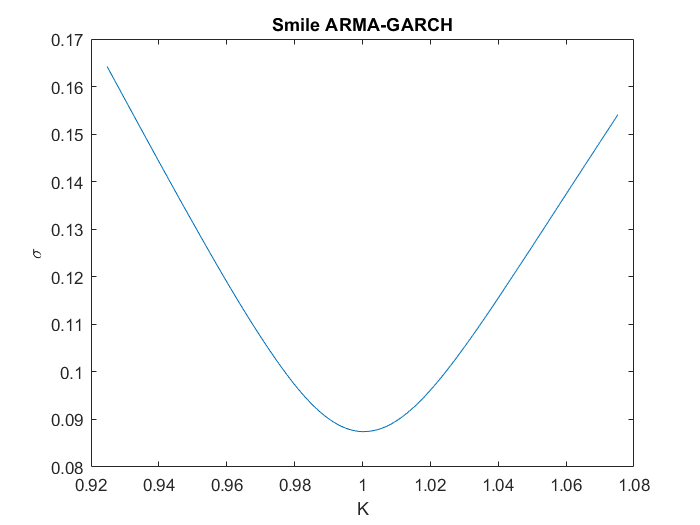


plot(K,implieds)
title('Smile ARMA-GARCH')
xlabel('K')
ylabel('\sigma')


% option3maaned=mean(max(S(86,:)-K,0))*exp(-(r/251)*86)
% %fire måneder frem. 86 dage.
% option4maaned=mean(max(S(80,:)-K,0))*exp(-(r/251)*86)
% 
% 
% 

function [ll,lls,h,fejlled]=ARMA_GARCH(parameters, logreturn, backCast)

c=parameters(1);
beta=parameters(2);
alpha=parameters(3);
konstant=parameters(4);
konstant2=parameters(5);

T=size(logreturn,1);
h=zeros(T,1);
h(1)=backCast;
fejlled=zeros(T,1);
%Jeg issolerer for fejlled i ligningen for afkast under P

for i=2:T
    fejlled(i)=logreturn(i)-konstant-konstant2*logreturn(i-1);
    h(i)=c+beta*h(i-1)+alpha*(fejlled(i-1)).^2;
    
end
% v=length(logreturn)-length(parameters);
% if v<50
%     v = 2 + exp(v);
% else
%     v = 50 + log(v);
% end
 lls= 0.5*(log(pi*2)+log(h)+fejlled.^2./h);
% lls=1/2*(log(h)+(v+1)*log(1+fejlled.^2./(h.*(v-1))));

ll=  sum(lls);
end

% Det her er funktion der finder J i sandwhichformlen der bliver brugt til at finde variansen:
%J er her givet ved: J(i,j)=(f(parametre+en lille ændring i to
%dimensioner)-f(parametre+lille ændring i en af
%parameter)-f(parametrene+lille ændring i den anden
%parametre)+f(parametrene))/(den lille ændring i hvet af parametrene ganget
%sammen).
function H= hessian_beggesider(funktion,parametre,varargin)
if size(parametre,2)>size(parametre,1)
    parametre=parametre';
end
%Jeg evaluere funktion med parametrene 
f=feval(funktion,parametre,varargin{:});
%En meget lille ændring af parametrene.
h=abs(parametre)*0.00001;
parametreh=h+parametre;
h=parametreh-parametre;
h=diag(h);

antal=size(parametre);

afledtep=zeros(antal);
afledten=zeros(antal);
%Jeg finder scoren lidt til over og under parametre væriderne.
for i=1:antal
    afledtep(i)=feval(funktion, parametre+h(:,i),varargin{:});
    afledten(i)=feval(funktion, parametre-h(:,i),varargin{:});
end
andenafledtep=zeros(antal);
andenafledten=zeros(antal);
%Nedenunder finder jeg de andenafledte ved at ændre to variable samtidigt.
for j=1:antal
    for i=j:antal
        andenafedtep(i,j)=funktion(parametre+h(:,j)+h(:,i),varargin{:});
        andenafledtep(j,i)=andenafledtep(i,j);
        andenafledten(i,j)=funktion(parametre-h(:,j)-h(:,i),varargin{:});
        andenafledten(j,i)=andenafledten(i,j);
    end
end
H=zeros(antal);
diagonal=diag(h);
GH=diagonal*diagonal';
%Tilsidst samles det hele sådan at J fås  
for i=1:antal
    for j=i:antal
        H(i,j)=(andenafledtep(i,j)+andenafledten(i,j)-afledtep(i)-afledten(i)-afledtep(j)-afledten(j)+f+f)/GH(i,j)/2;
        H(j,i)=H(i,j);
    end
end
end
